# Vectorized programing in Matlab

The key to proper programing in Matlab is to understand vectorization. Vectorization speeds up Matlab code dramatically and makes it more readable. All code for this class has to be written vectorized! 

## What is vectorization?

Suppose you have two vectors $\mathbf{a}$ and $\mathbf{b}$ that represent two functions.

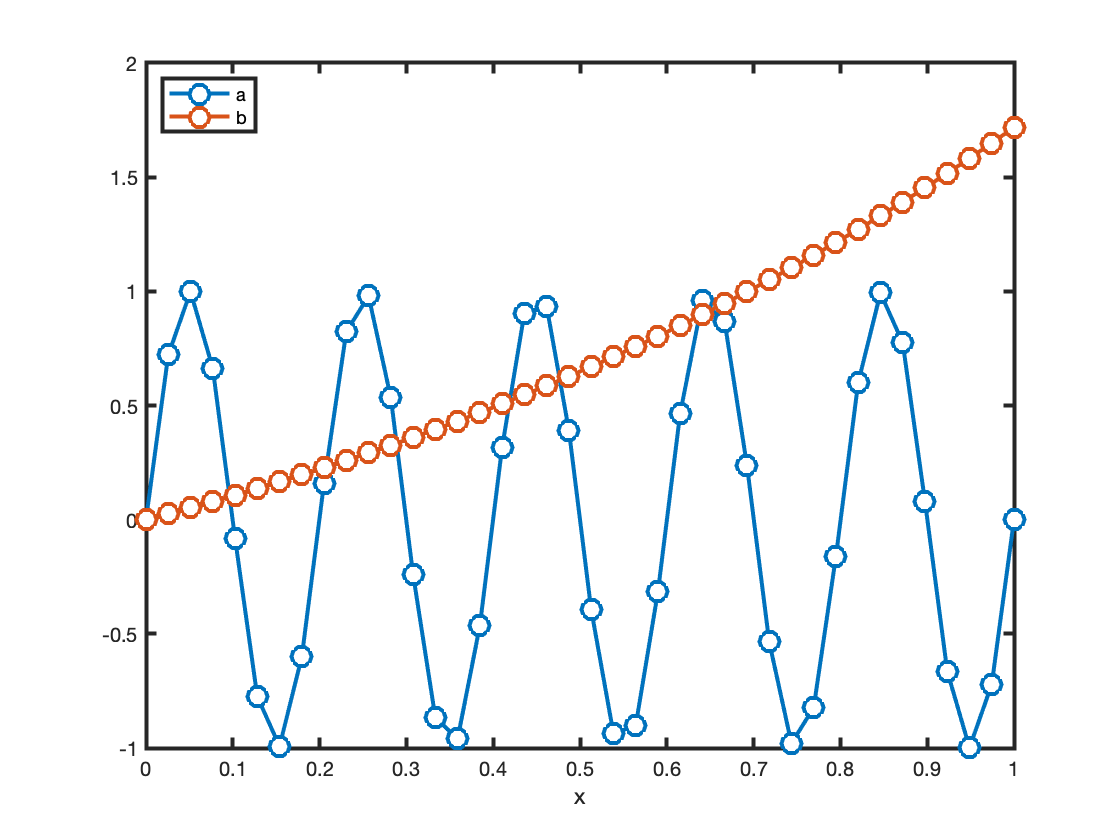

clear all, close all
set_defaults();
x = linspace(0,1,40);
a = sin(10*pi*x);
b = exp(x)-1;
plot(x,a,'o-','markersize',10,'markerfacecolor','w'), hold on
plot(x,b,'o-','markersize',10,'markerfacecolor','w'), hold off
xlabel 'x', legend('a','b','location','northwest')

Now you would like to compute the discrete representation of the function $f(x) = \exp(x)\sin(10\pi x))$, by multiplying the entries of $\mathbf{a}$ and $\mathbf{b}$ elementwise. In Fortran or C++ you do this using a for-loop as follows.

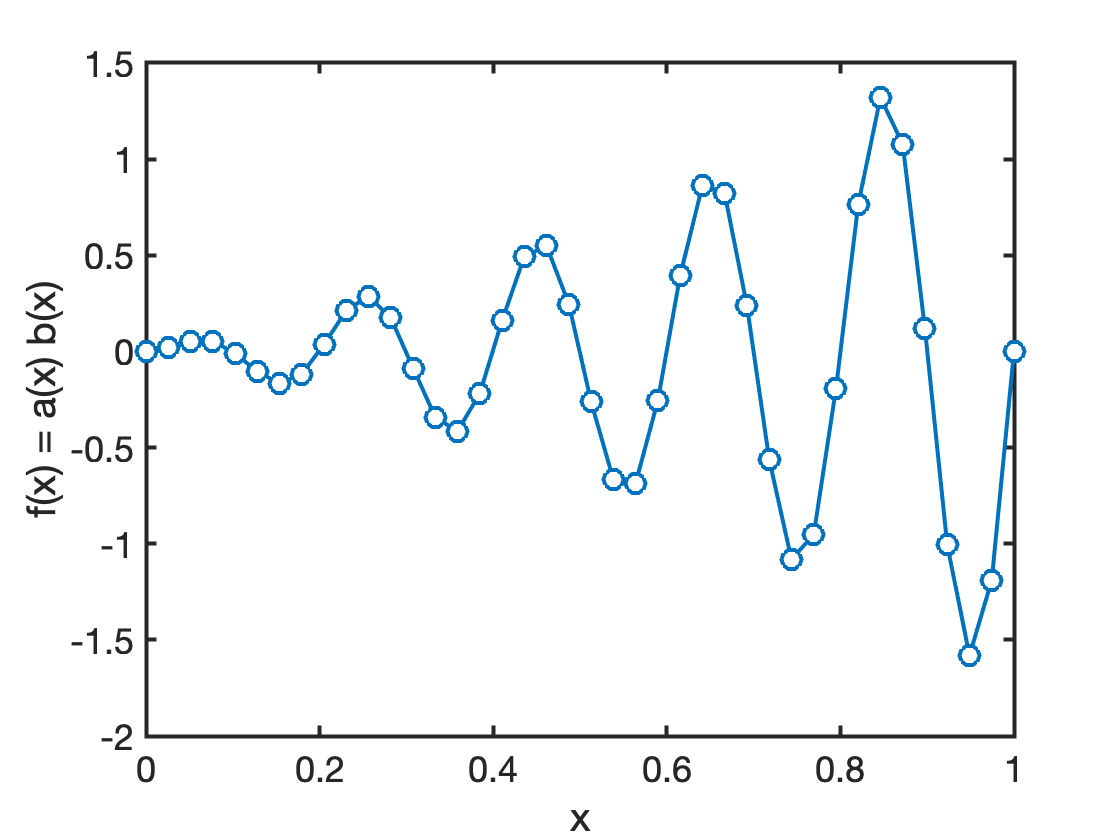

clear f
N = length(a);
for n = 1:N
    f(n) = a(n)*b(n);
end
plot(x,f,'o-','markersize',10,'markerfacecolor','w')
xlabel('x'), ylabel('f(x) = a(x) b(x)')

In Matlab you can also do this vectorized, i.e., without writing the for-loop explicitly. 

size(a)

ans =      1    40


size(b)

ans =      1    40


f1 = a*b'   % just scalar product of two vectors

f1 = -2.0143


f2 = a.*b;  % vectorized multiplication - note the DOT!
norm(f-f2)

ans = 0

Here the $f_1 = \sum_{n=1}^N a_nb_n$ is the scalar product and hence a single number. In contrast $\mathbf{f}_2$ is a vector such that the *n*-th entry is $f_{2,n} = a_n b_n $. This is refereed to as "element-wise multiplication" and equifalent to the for-loop above.

In Matlab this for-loop becomes very slow as N increases. The code below demonstrates this and uses the [tic-toc](https://www.mathworks.com/help/matlab/ref/tic.html) function in Matlab to compare vectorised and for-loop implementation.

Nvec = [1e1 1e2 1e3 1e4 1e5 1e6];
for i=1:length(Nvec)
    N = Nvec(i);
    x = linspace(0,1,N);
    a = sin(10*pi*x);
    b = exp(x)-1;
    clear f_loop f_vec
    % Vectorized
    tic
    f_vec = a.*b;
    time_vec(i) = toc;
    pause(.1)
    % For-loop
    tic
    for n = 1:N
        f_loop(n) = a(n)*b(n);
    end
    time_for(i) = toc;
    pause(.1)
    fprintf('N = %2.0e: t_vec = %3.2e [sec]; t_for = %3.2e.\n',N,time_vec(i),time_for(i))
end

N = 1e+01: t_vec = 9.32e-04 [sec]; t_for = 1.40e-03.
N = 1e+02: t_vec = 3.78e-05 [sec]; t_for = 1.29e-03.
N = 1e+03: t_vec = 1.90e-04 [sec]; t_for = 2.46e-03.
N = 1e+04: t_vec = 7.32e-05 [sec]; t_for = 2.48e-02.
N = 1e+05: t_vec = 1.03e-03 [sec]; t_for = 2.12e-01.
N = 1e+06: t_vec = 2.76e-03 [sec]; t_for = 2.17e+00.


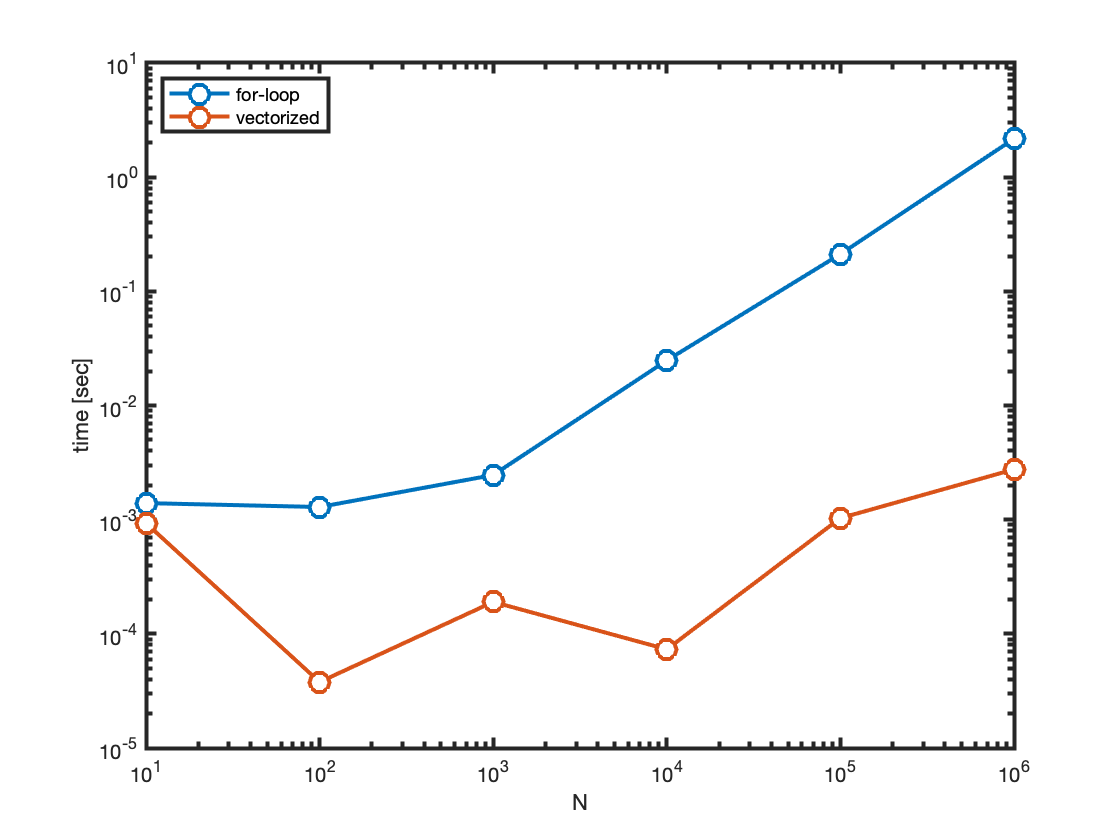

loglog(Nvec,time_for,'o-','markersize',10,'markerfacecolor','w'), hold on
loglog(Nvec,time_vec,'o-','markersize',10,'markerfacecolor','w'), hold off
legend('for-loop','vectorized','location','northwest')
xlabel('N'), ylabel('time [sec]')

When the vectors become longer for-loop is increasingly slow compared to the vectrized implementation. Vectorized implementation is therefore always preferred. If the for-loop cannot be avoided,Matlab claims  it can be accelerated significantly by pre-allocating the memory for the new vector $\mathbf{f}$. As you will see below this is not very significant.

for i=1:length(Nvec)
    N = Nvec(i);
    x = linspace(0,1,N);
    a = sin(10*pi*x);
    b = exp(x)-1;
    clear f_pre 
    % For-loop with pre-allocation
    tic
    f_pre = zeros(N,1);    
    for n = 1:N
        f_pre(n) = a(n)*b(n);
    end
    time_pre(i) = toc;
    pause(.1)
    fprintf('N = %2.0e: t_pre = %3.2e.\n',N,time_pre(i))
end

N = 1e+01: t_pre = 8.79e-04.
N = 1e+02: t_pre = 2.14e-04.
N = 1e+03: t_pre = 1.18e-02.
N = 1e+04: t_pre = 2.36e-02.
N = 1e+05: t_pre = 1.99e-01.
N = 1e+06: t_pre = 1.72e+00.


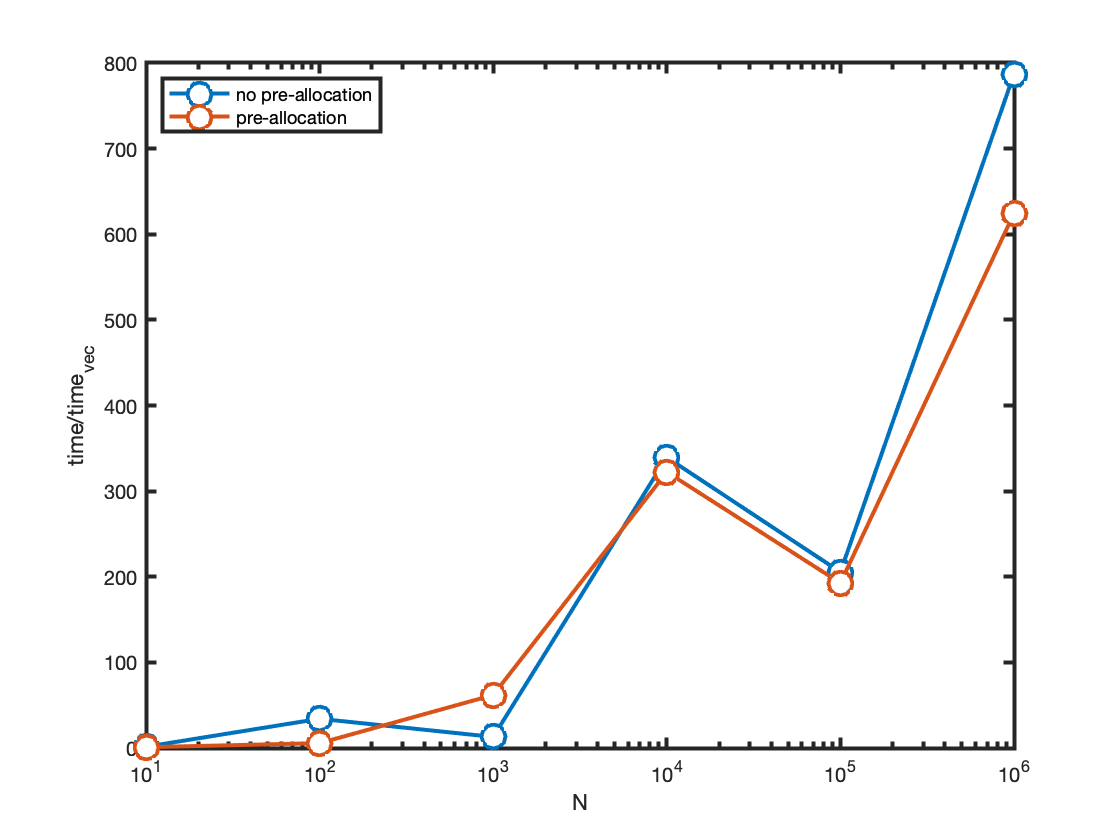


semilogx(Nvec,time_for./time_vec,'o-','markerfacecolor','w'), hold on
semilogx(Nvec,time_pre./time_vec,'o-','markerfacecolor','w'), hold off
xlabel('N'), ylabel('time/time_{vec}')
legend('no pre-allocation','pre-allocation','location','northwest')

## Vectorization also works for matrices!

Despite the name the idea of "element-by-element" operations also translates to matrices and in fact any type of array. 

This is most commonly used in plotting 2D and 3D functions.Suppose we want to plot the functions $g(x,y) =\frac{\sin(10\pi x) e^{-x}}{2+5y}$ on the domain $x\in\left[0,\,1\right]$ and $y\in\left[0,\,1\right]$. First we generate equally spaced vectors $\mathbf{x}$ and $\mathbf{y}$ and replicate them into matrices $\mathbf{X}$ and $\mathbf{Y}$ using the Matlab function [meshgrid](https://www.mathworks.com/help/matlab/ref/meshgrid.html). A matrix $\mathbf{G}$ containing the function values can the be evaluated vectorized.

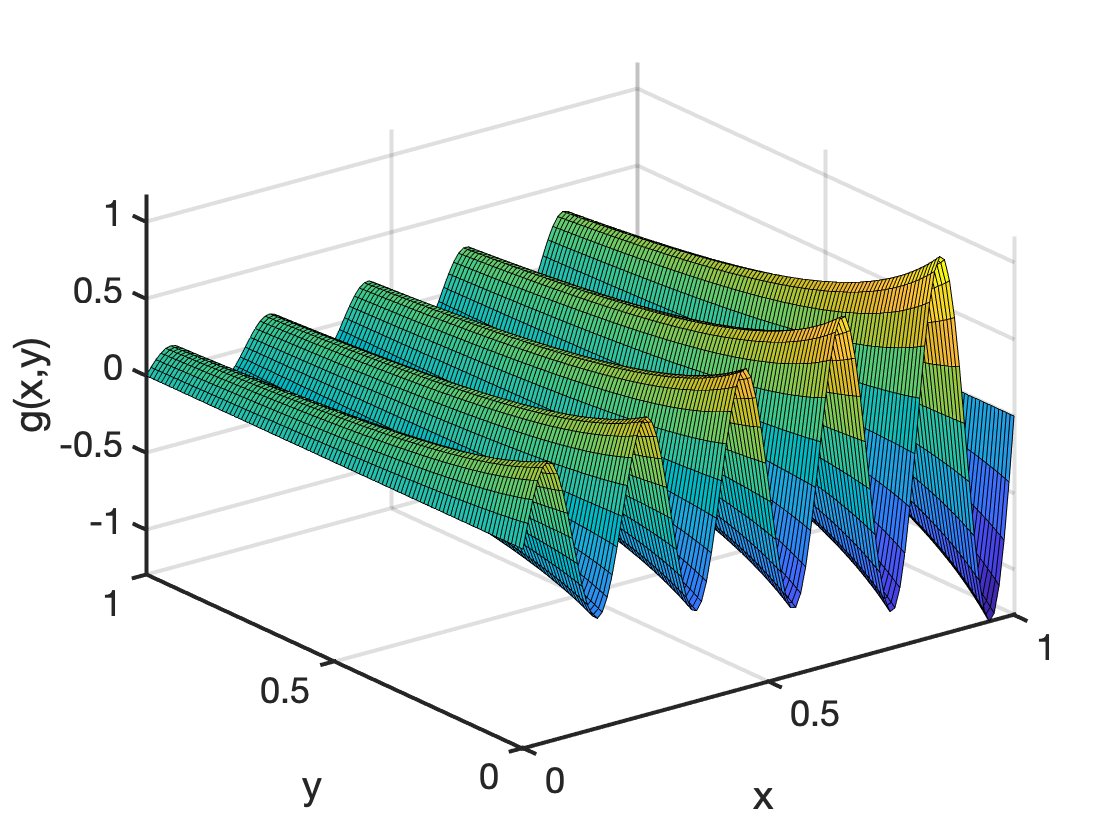

x = linspace(0,1,1e2); y = x;
[X,Y] = meshgrid(x,y);
G = sin(10*pi*X).*exp(X)./(2+5*Y);
surf(X,Y,G)
xlabel('x'), ylabel('y'), zlabel('g(x,y)')

## Some general notes on vectorization

For vectorization to work all arrays must have the same dimension. The most common reason for vectorized code to fail is that the array dimensions do not match. In this case, Matlab will give an error message "Matrix dimensions must agree".

A = rand(3,4); B = rand(4,5);
% C = A.*B;

In this case, use the Matlab function size to investigate the dimensions of the arrays.

size(A)

ans =      3     4


size(B)

ans =      4     5


Not all mathematical operations require vercorization. Addition, subtraction and scalar multiplication do not require vectorization. Multiplication and division do need vectorization. 

## Auxillary function definitions

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end